MapNumber = 4

MapNumber = 4

mapData = load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\3D\occupancy_map_3d" + MapNumber + ".mat")

mapData = struct with fields:
    omap3D: [1×1 occupancyMap3D]


omap = mapData.omap3D

omap =   occupancyMap3D with properties:

    ProbabilitySaturation: [1.0000e-03 0.9990]
               Resolution: 1
        OccupiedThreshold: 0.6500
            FreeThreshold: 0.2000


omap.FreeThreshold = omap.OccupiedThreshold;


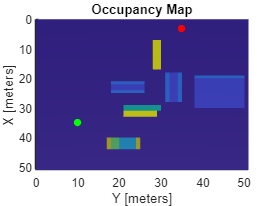

%startPose = [3 35 3 pi/2];
%goalPose = [35 10 4 pi/2];
startPose = [3 35 3 pi/2];
goalPose = [35 10 5 pi/2];
figure("Name","StartAndGoal")
hMap = show(omap);
hold on
scatter3(hMap,startPose(1),startPose(2),startPose(3),30,"red","filled")
scatter3(hMap,goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
hold off
view([90 90])

ss = UAVstatespace("MaxRollAngle",pi/6,...
                                "AirSpeed",1,...
                                "FlightPathAngleLimit",[-0.1 0.1],...
                                "Bounds",[0 100; 0 50; 0.5 100; -pi pi]);

% stateSamplerDL = stateSamplerMPNET(ss,mpnet);
% 
% start = robot_pose;
% goal = goal_pose;
% 
% stateSamplerDL.Environment = map;
% stateSamplerDL.StartState = start;
% stateSamplerDL.GoalState = goal;

threshold = [(goalPose-2.5)' (goalPose+2.5)'; -pi pi];

setWorkspaceGoalRegion(ss,goalPose,threshold)


sv = validatorOccupancyMap3D(ss,"Map",omap);
sv.ValidationDistance = 0.01;







planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 30;
planner.GoalBias = 0.11;  
planner.MaxIterations = 10000;
planner.GoalReachedFcn = @(~,x,y)(norm(x(1:3)-y(1:3)) < 2);

[pthObj,solnInfo] = plan(planner,startPose,goalPose)

pthObj =   navPath with properties:

      StateSpace: [1×1 UAVstatespace]
          States: [3×4 double]
       NumStates: 3
    MaxNumStates: Inf


solnInfo = struct with fields:
      IsPathFound: 1
         ExitFlag: 1
         NumNodes: 12
    NumIterations: 12
         TreeData: [38×4 double]


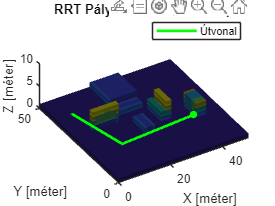

if (solnInfo.IsPathFound)
    figure("Name","OriginalPath")
    % Visualize the 3-D map
    show(omap)
    hold on
    %scatter3(startPose(1),startPose(2),startPose(3),30,"red","filled")
    scatter3(goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
    
    interpolatedPathObj = copy(pthObj);
    interpolate(interpolatedPathObj,1000)
    
    % Plot the interpolated path based on UAV Dubins connections
    hReference = plot3(interpolatedPathObj.States(:,1), ...
        interpolatedPathObj.States(:,2), ...
        interpolatedPathObj.States(:,3), ...
        "LineWidth",2,"Color","g");
    
    legend([hReference],"Útvonal","Location","best")
    title("RRT Pályatervezés, "+ MapNumber +". térkép")
    xlim([0 50])
    ylim([0 50])
    zlim([0 10])
    xlabel("X [méter]")
    ylabel("Y [méter]")
    zlabel("Z [méter]")

    hold off
    view([-31 63])
end

DataMatrixRRT = [interpolatedPathObj.States(:,1) interpolatedPathObj.States(:,2) interpolatedPathObj.States(:,3)]

DataMatrixRRT =     3.0000   35.0000    3.0000
    3.0101   35.0590    3.0060
    3.0394   35.1113    3.0121
    3.0845   35.1507    3.0181
    3.1401   35.1729    3.0242
    3.2000   35.1752    3.0302
    3.2571   35.1574    3.0362
    3.3051   35.1215    3.0423
    3.3383   35.0717    3.0483
    3.3530   35.0136    3.0543


save("3D\RLVFH\RRT" + MapNumber +".mat", "DataMatrixRRT")